# Image 7

## 1) Median Filter -> Gaussian Filter -> Gabor filter

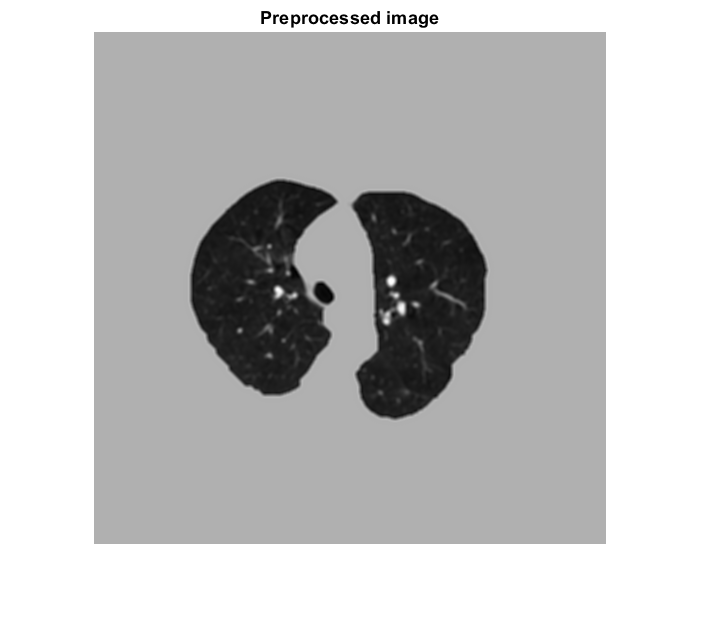

%Read in image and extract lungs 
I = dicomread('p1_img7.dcm');
preprocessedI = lungExtraction(I,strel('disk',15),1);

%Adaptive histogram doesnt seem to work. Removed it from the process.
I_pre = pre1(preprocessedI); 
figure,imshow(I_pre,[]);title('Preprocessed image');

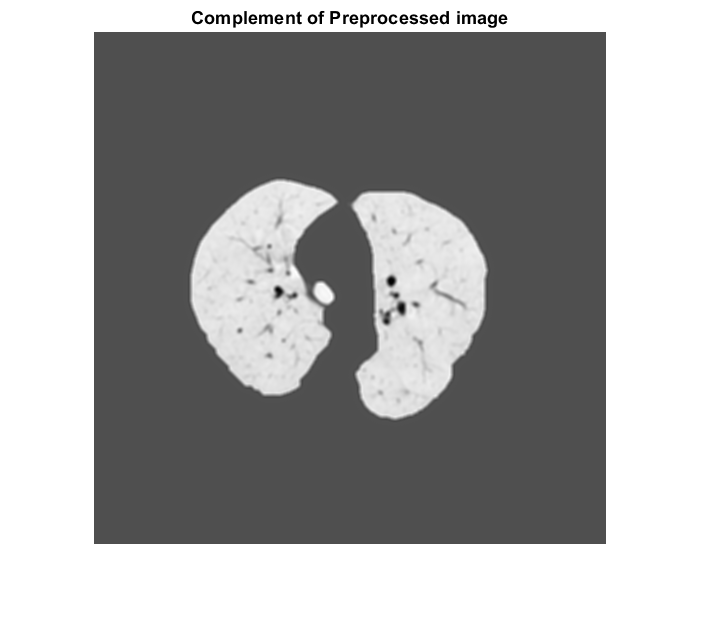


%Complement the gabor image to change background to white from black
I_pre = imcomplement(I_pre);
figure,imshow(I_pre,[]);title('Complement of Preprocessed image');

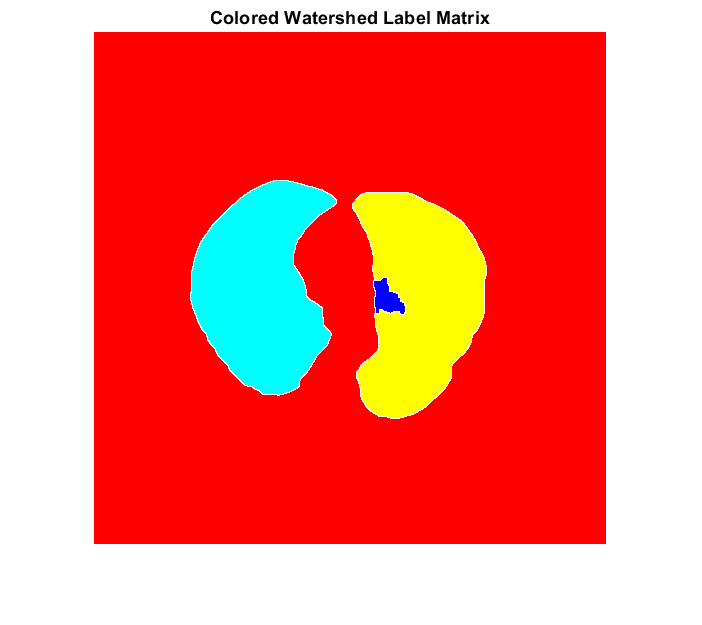

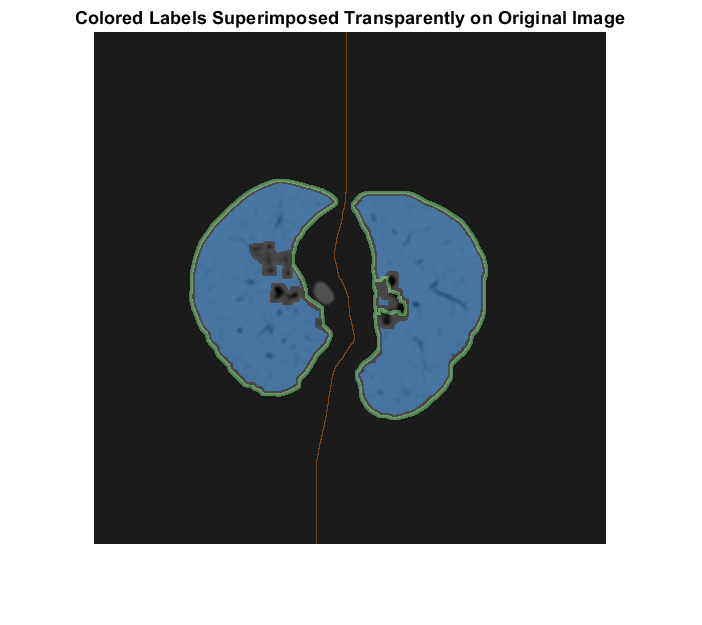


%Apply watershed on preprocessed image
label = markcontrwatershed(I_pre,strel('disk',17),strel(ones(5,5))); 

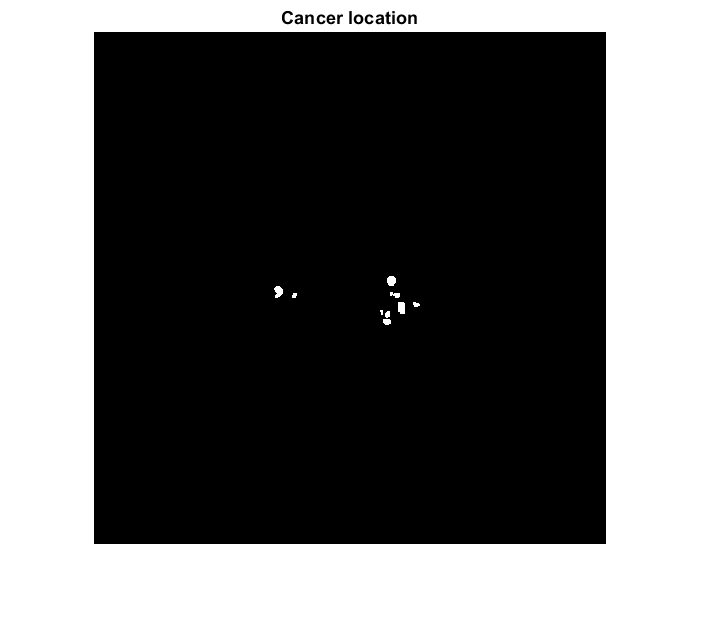


%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

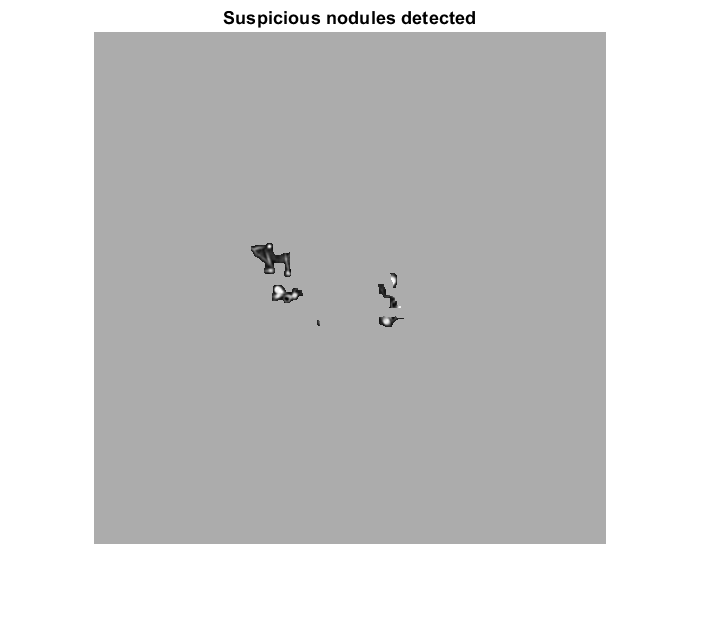


%Get suspicious nodules
nodules = noduleExtraction(label,preprocessedI);


%Label suspicious nodules
[L, num] = bwlabel(nodules);
disp (num);

     6



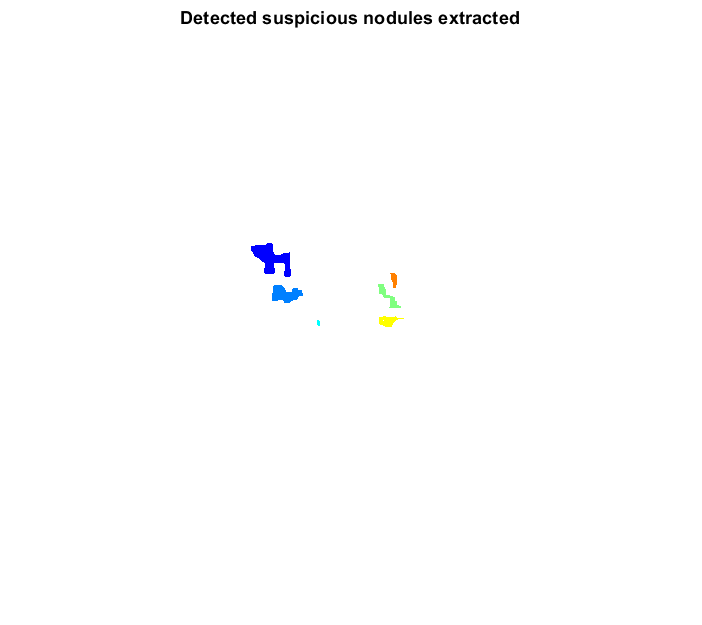

RGB = label2rgb(L);
figure, imshow(RGB),title('Detected suspicious nodules extracted');

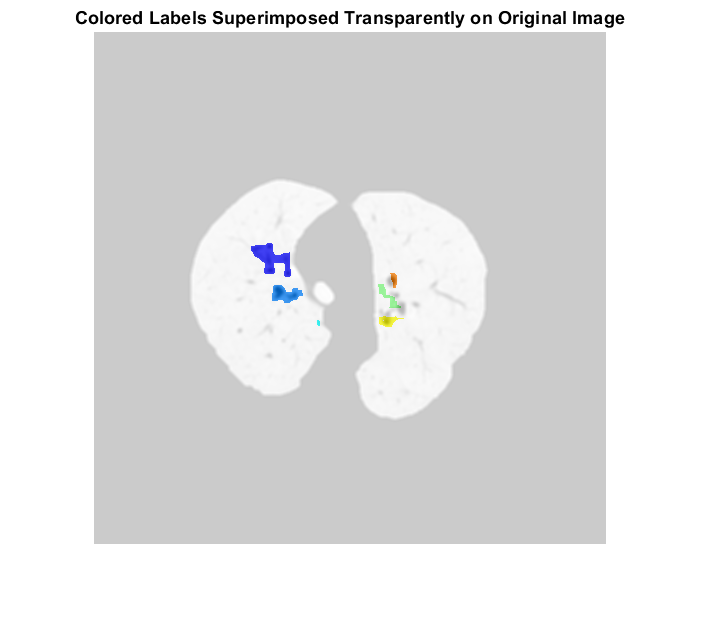


figure,
imshow(I_pre,[])
hold on
himage = imshow(RGB);
himage.AlphaData = 0.7;
title('Colored Labels Superimposed Transparently on Original Image')

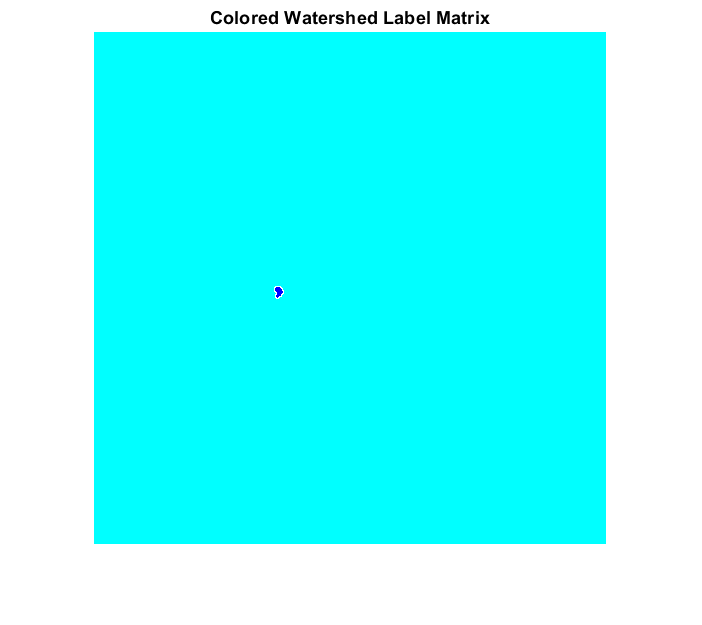

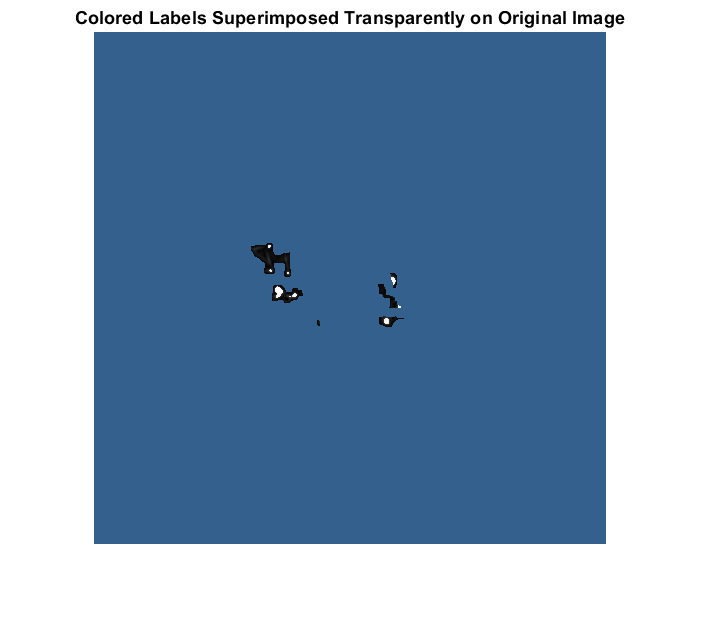


%Watershed on suspicious cells.
markcontrwatershed(nodules,strel('disk',3),strel(ones(1,1)));

%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

[truePos,falsePos] = falseTruePositives(nodules,dicomread('p1_seg7.dcm'));
truePos

truePos = 0.4500

falsePos

falsePos = 3.7525

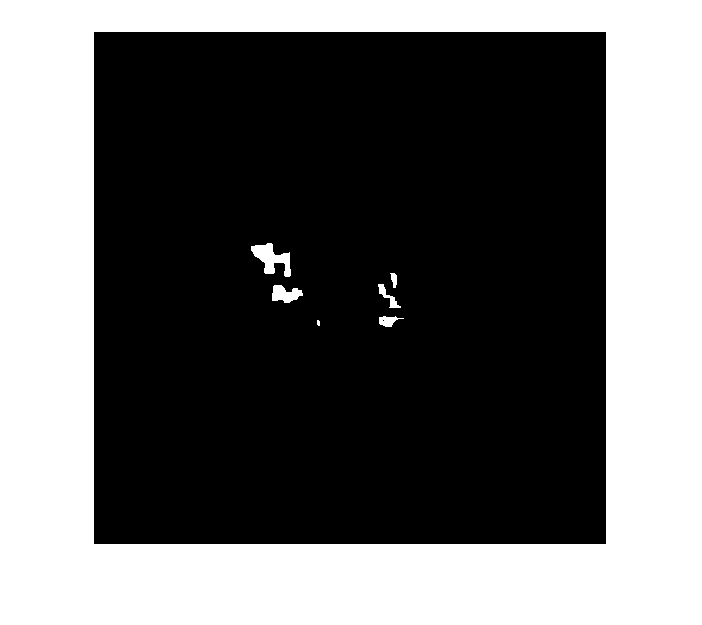

%Get percentage correct of suspicious regions based on cancer location of
%ground truth
%do thresholding on nodules
nodulesThresh = nodules;
nodulesThresh(nodules < 0 | nodules > 0) = 1;
nodulesThresh(nodules == 0) = 0;
nodulesThresh = cast(nodulesThresh,'logical');
imshow(nodulesThresh,[]);


groundTruth = dicomread('p1_seg7.dcm');
groundTruth = imbinarize(groundTruth);
figure,imshow(groundTruth,[]),title('Cancer location');

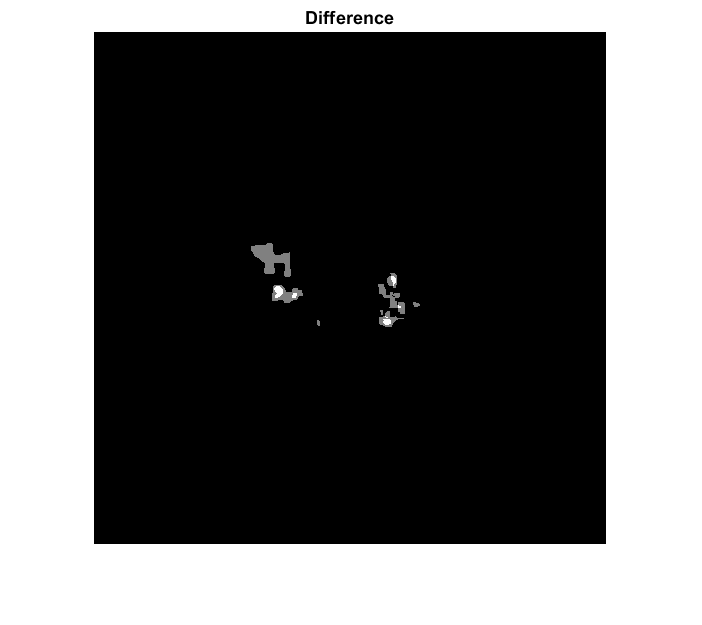


diff = nodulesThresh + groundTruth;
figure,imshow(diff,[]),title('Difference');


%Number of unique values for diff
c = unique(diff)

c =      0
     1
     2


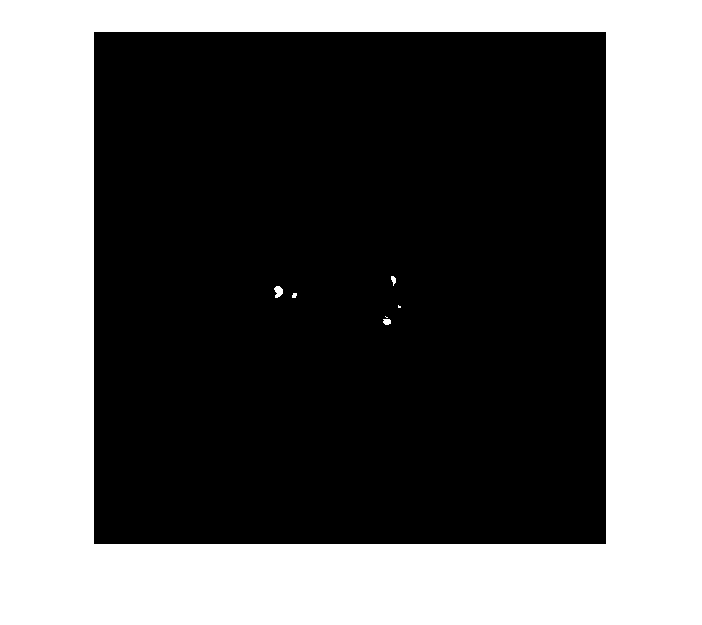


%True positives
truePos = diff;
truePos(diff == 1) = 0;
figure,imshow(truePos,[]);

unique(truePos)

ans =      0
     2


%get number of truePos
numTruePos = sum(truePos(:) == 2)

numTruePos = 180

%ratio based on ground truth
percenNumTruePos = numTruePos / sum(groundTruth(:) == 1) 

percenNumTruePos = 0.4500

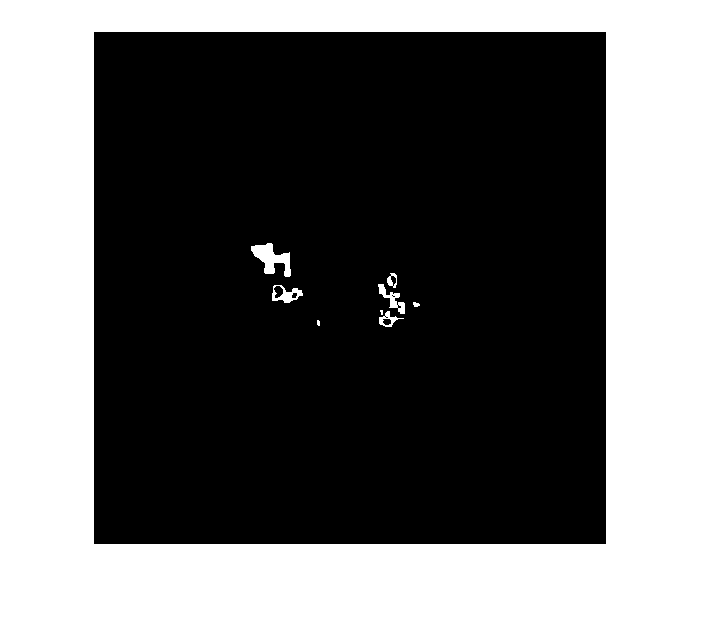


%False positives
falsePos = diff;
falsePos(diff == 2) = 0;
figure,imshow(falsePos,[]);

unique(falsePos)

ans =      0
     1


%get number of falsePos
numFalsePos = sum(falsePos(:) == 1)

numFalsePos = 1501

percenNumFalsePos = numFalsePos / sum(groundTruth(:) == 1) 

percenNumFalsePos = 3.7525

## 2) Gabor filter 

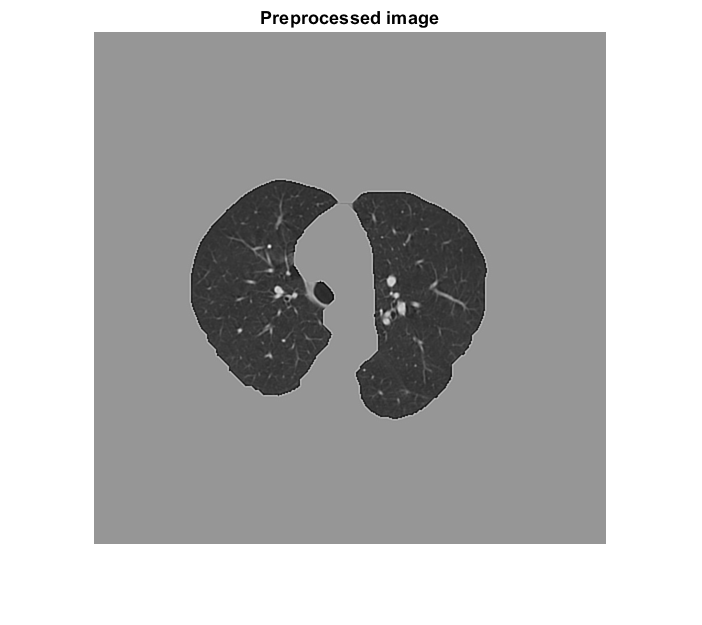

%Read in image and extract lungs 
I = dicomread('p1_img7.dcm');
preprocessedI = lungExtraction(I,strel('disk',15),1);

I_pre = pre2(preprocessedI);
figure,imshow(I_pre,[]);title('Preprocessed image')

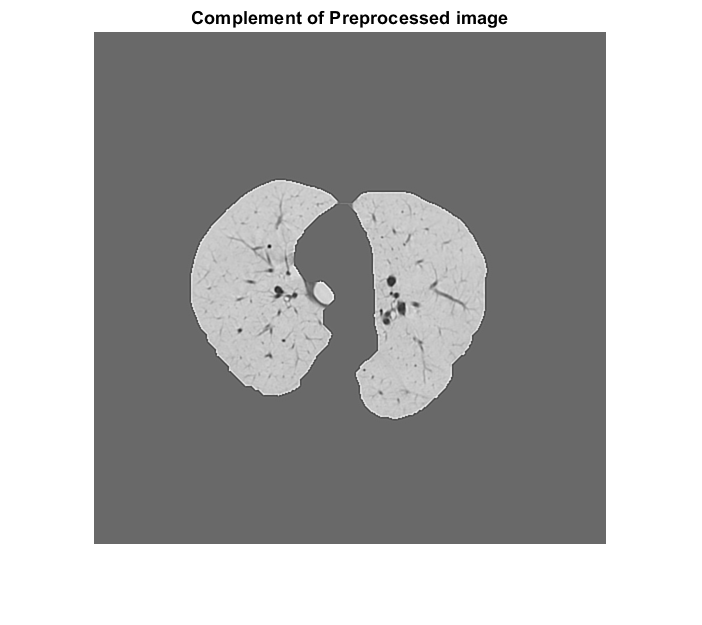


%Complement the gabor image to change background to white from black
I_pre = imcomplement(I_pre);
figure,imshow(I_pre,[]);title('Complement of Preprocessed image')

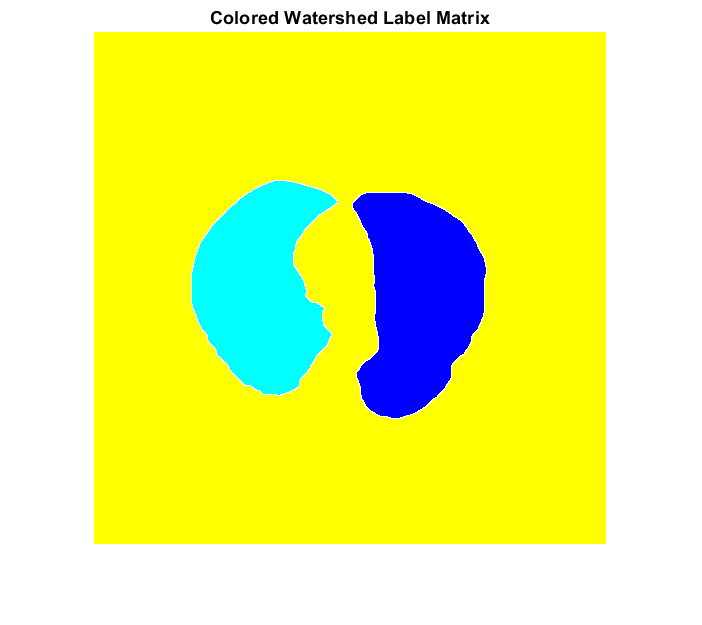

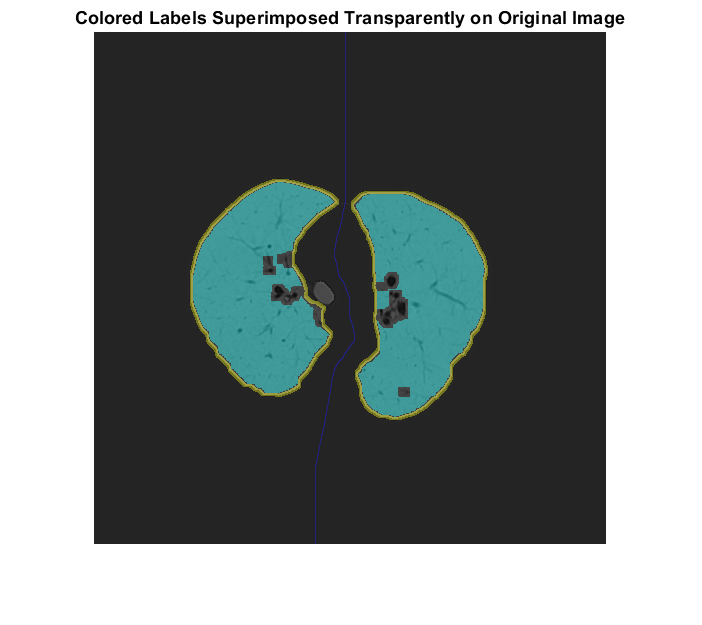


%Apply watershed on preprocessed image
label = markcontrwatershed(I_pre,strel('disk',10),strel(ones(5,5))); 


%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location'); 

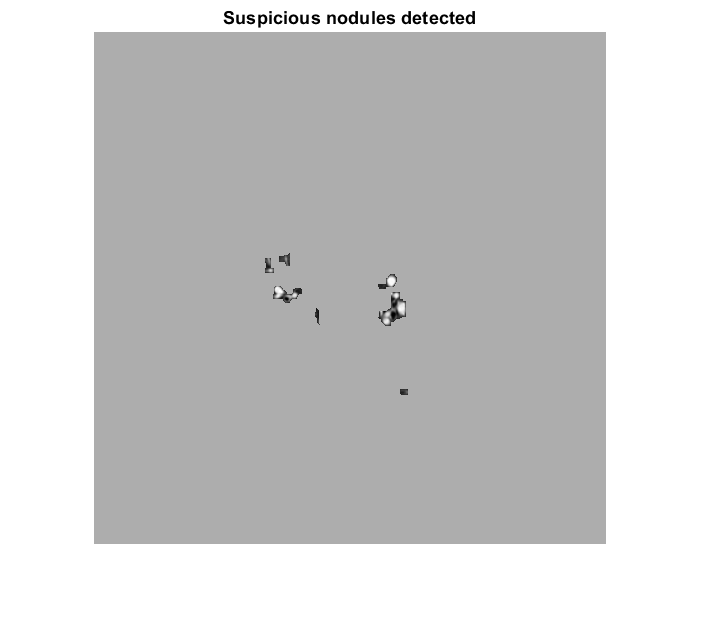


%Get suspicious nodules
nodules = noduleExtraction(label,preprocessedI);


%Label suspicious nodules
[L, num] = bwlabel(nodules);
disp (num);

     7



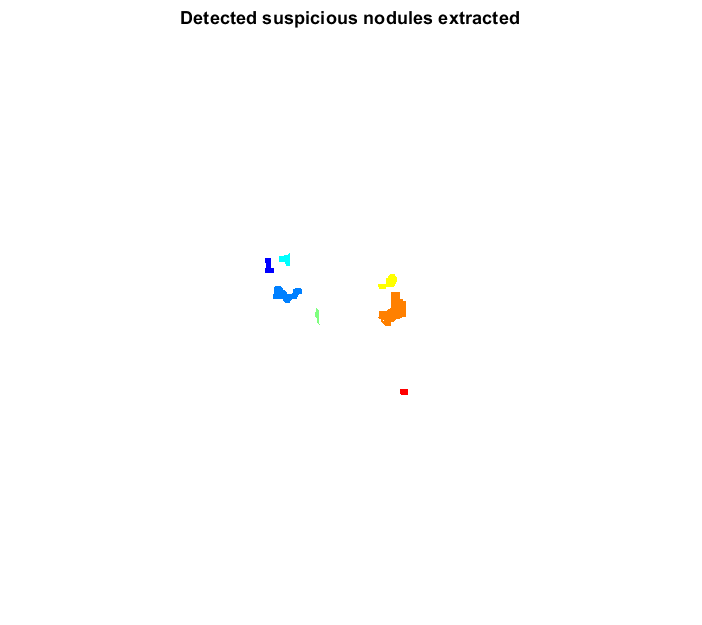

RGB = label2rgb(L);
figure, imshow(RGB),title('Detected suspicious nodules extracted');

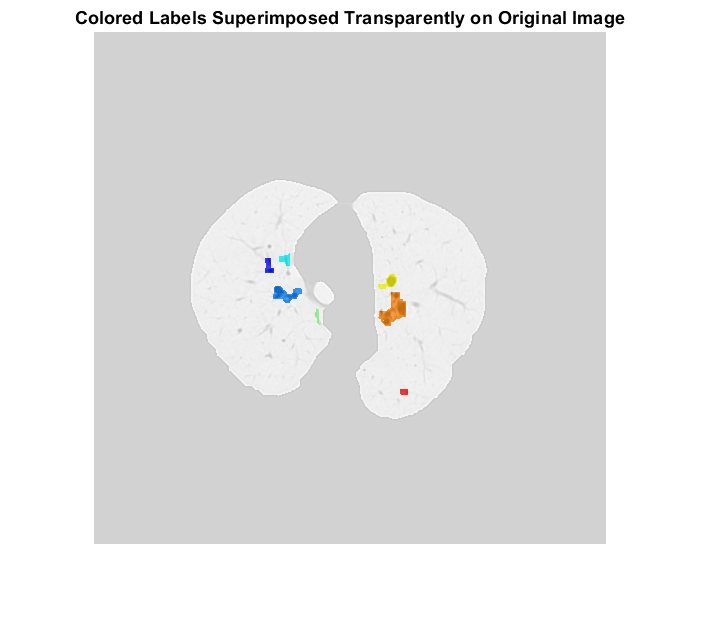


%To choose a certain object
%figure,imshow(L == 2)
%title('Object 2');

figure,
imshow(I_pre,[])
hold on
himage = imshow(RGB);
himage.AlphaData = 0.7;
title('Colored Labels Superimposed Transparently on Original Image')

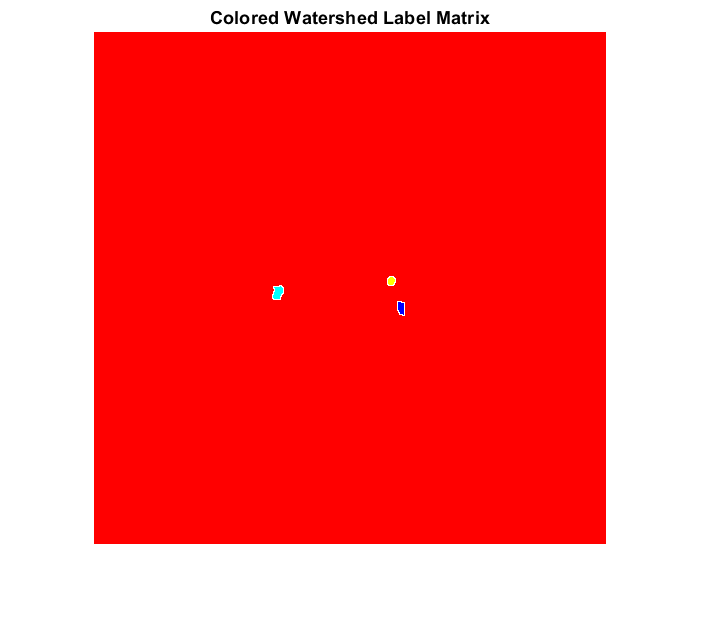

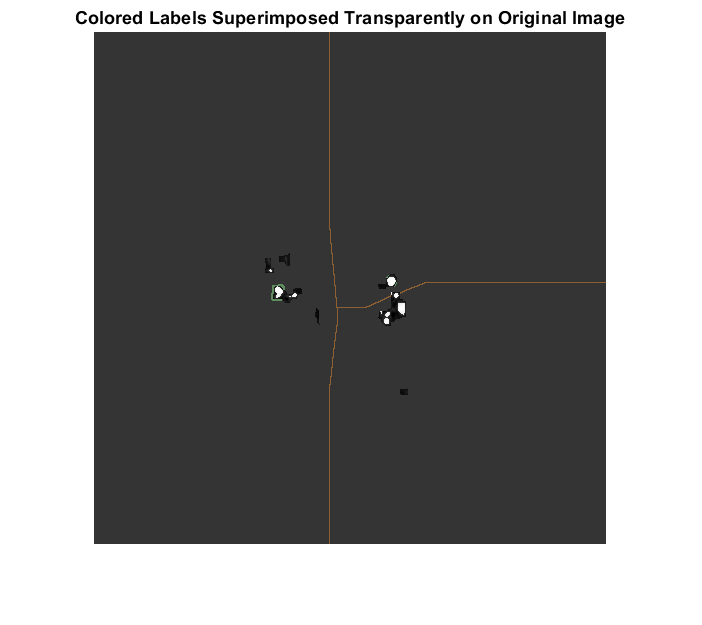


%Watershed on suspicious cells.
markcontrwatershed(nodules,strel('disk',3),strel(ones(1,1)));

%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

[truePos,falsePos] = falseTruePositives(nodules,dicomread('p1_seg7.dcm'));
truePos

truePos = 0.9150

falsePos

falsePos = 2.2900

## 3) Median filter -> Gaussian filter 

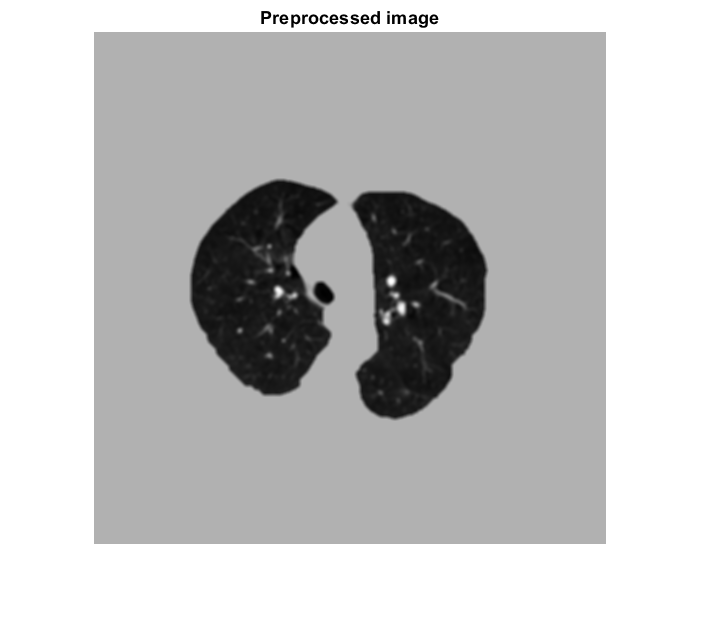

%Read in image and extract lungs 
I = dicomread('p1_img7.dcm');
preprocessedI = lungExtraction(I,strel('disk',15),1);

I_pre = pre3(preprocessedI);
figure,imshow(I_pre,[]);title('Preprocessed image')

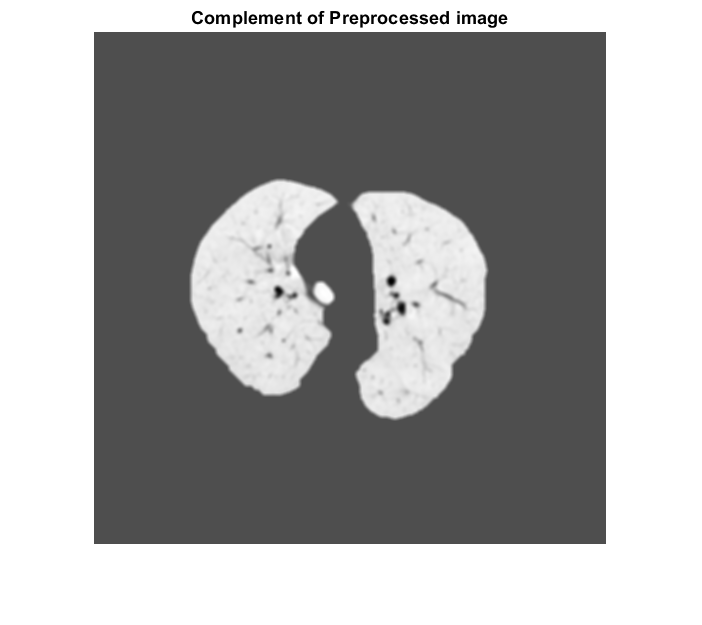


%Complement the gabor image to change background to white from black
I_pre = imcomplement(I_pre);
figure,imshow(I_pre,[]);title('Complement of Preprocessed image')

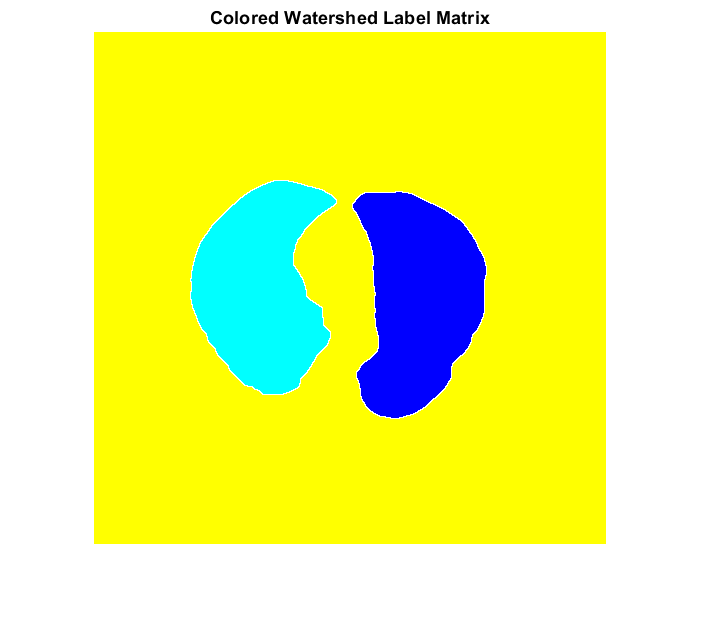

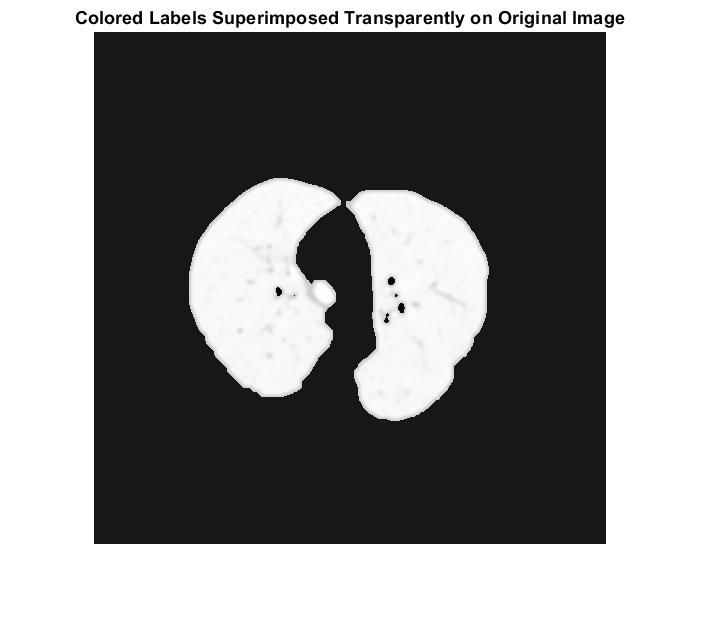


%Apply watershed on preprocessed image
label = markcontrwatershed(I_pre,strel('disk',17),strel(ones(5,5)));


%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

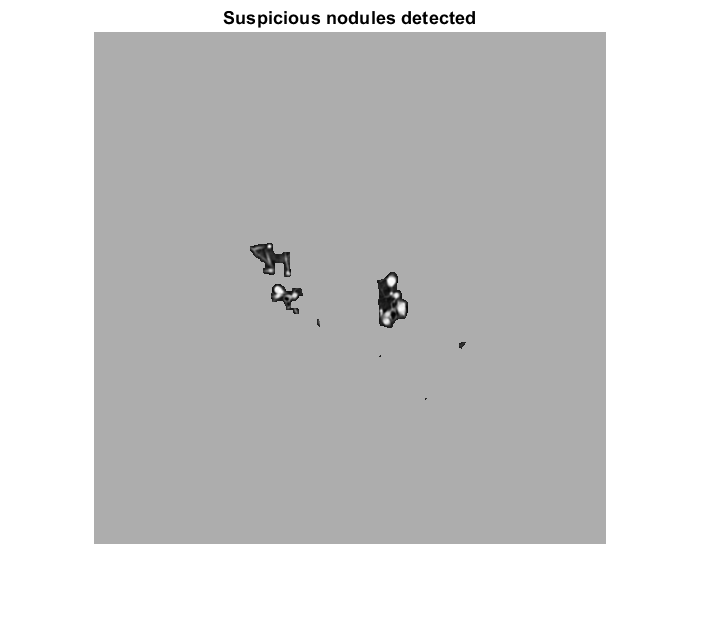


%Get suspicious nodules from original image. Using the filtered image too
%blurry.
nodules = noduleExtraction(label,preprocessedI);


[L, num] = bwlabel(nodules);
disp (num);

     7



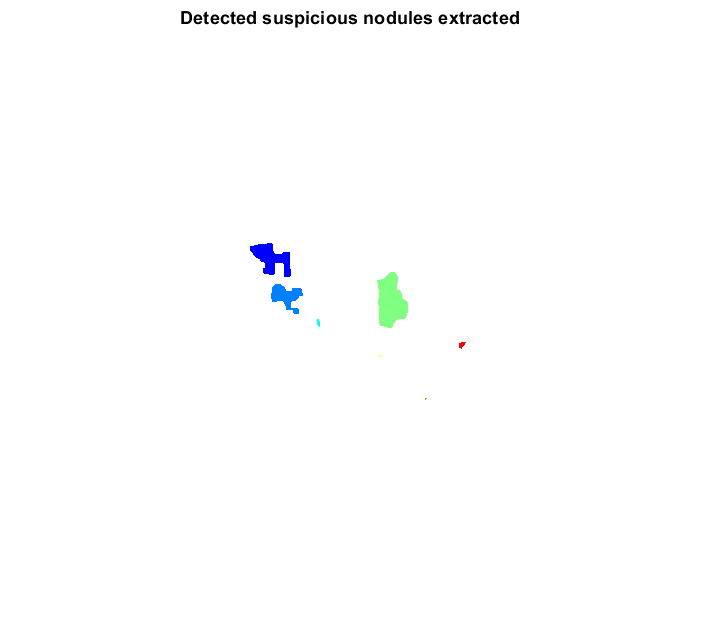

RGB = label2rgb(L);
figure, imshow(RGB),title('Detected suspicious nodules extracted');

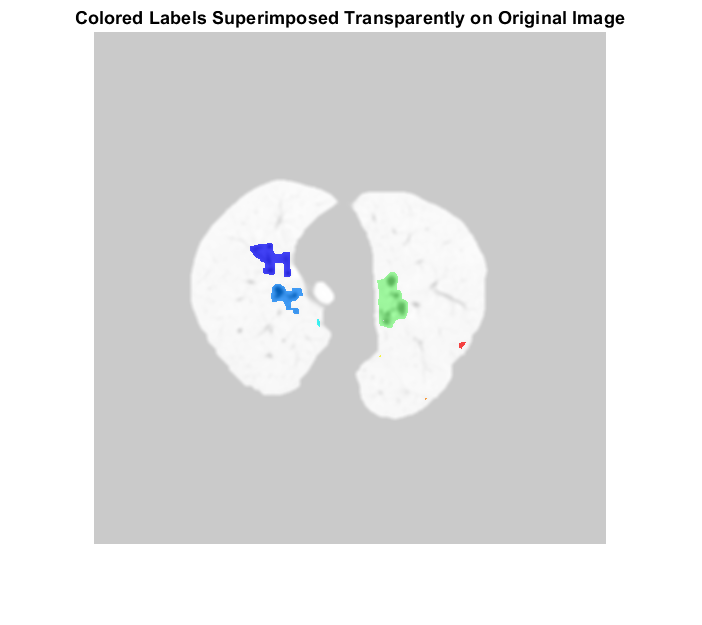


figure,
imshow(I_pre,[])
hold on
himage = imshow(RGB);
himage.AlphaData = 0.7;
title('Colored Labels Superimposed Transparently on Original Image')

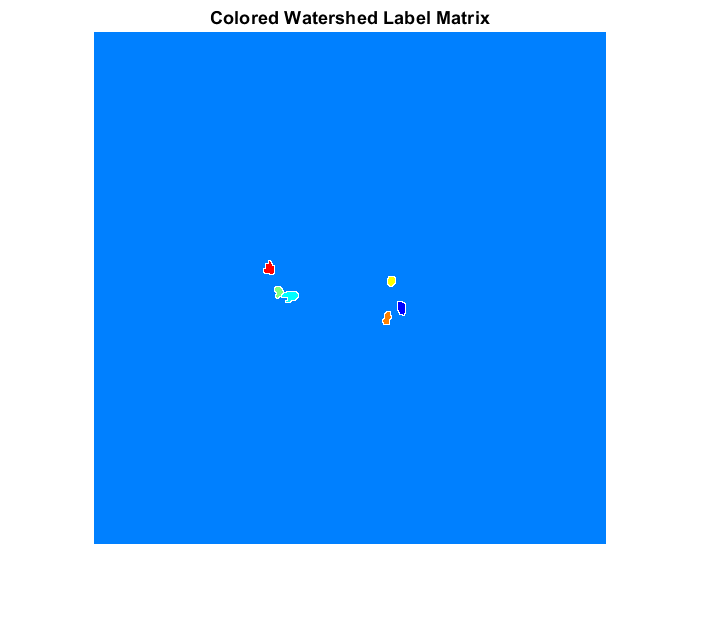

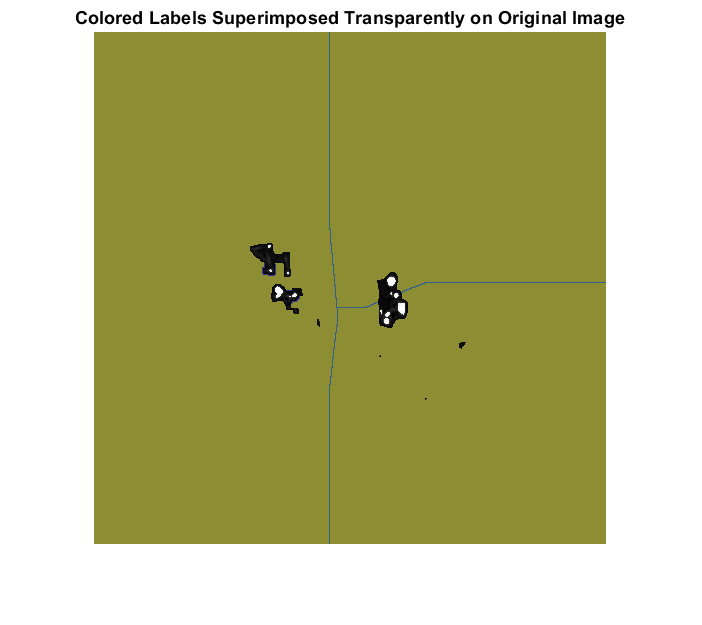


%Watershed on suspicious cells.
markcontrwatershed(nodules,strel('disk',3),strel(ones(1,1)));

%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

[truePos,falsePos] = falseTruePositives(nodules,dicomread('p1_seg7.dcm'));
truePos

truePos = 0.9325

falsePos

falsePos = 5.3050

## 4) Median filter

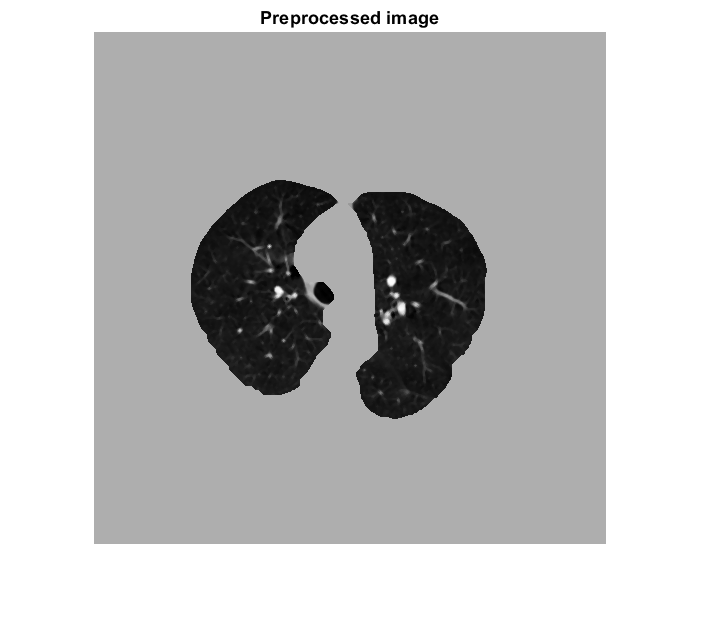

%Read in image and extract lungs 
I = dicomread('p1_img7.dcm');
preprocessedI = lungExtraction(I,strel('disk',15),1);

%Adaptive histogram doesnt seem to work. Removed it from the process.
I_pre = pre4(preprocessedI); 
figure,imshow(I_pre,[]);title('Preprocessed image');

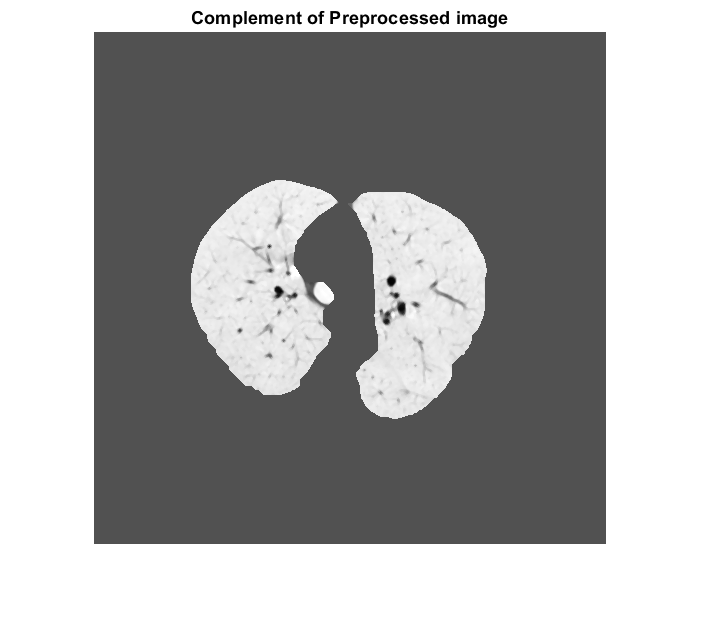


%Complement the gabor image to change background to white from black
I_pre = imcomplement(I_pre);
figure,imshow(I_pre,[]);title('Complement of Preprocessed image');

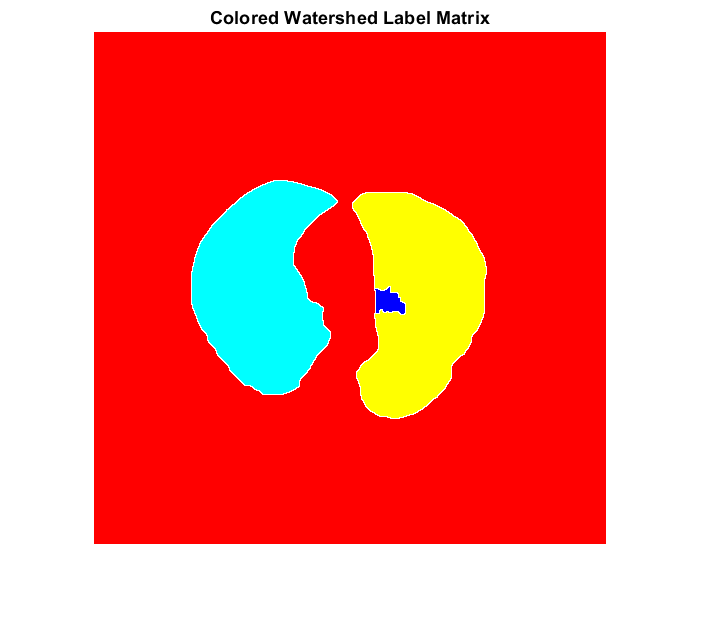

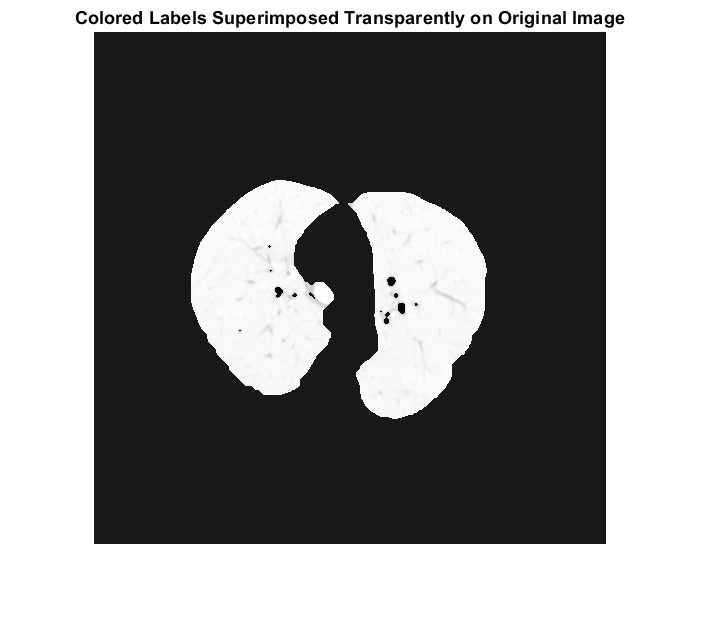


%Apply watershed on preprocessed image
label = markcontrwatershed(I_pre,strel('disk',15),strel(ones(5,5))); 


%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

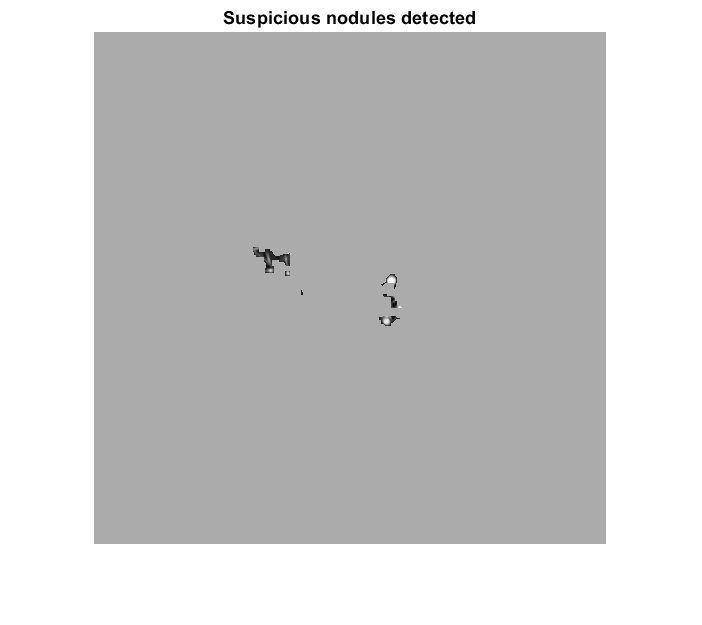


%Get suspicious nodules
nodules = noduleExtraction(label,preprocessedI);


%Label suspicious nodules
[L, num] = bwlabel(nodules);
disp (num);

     6



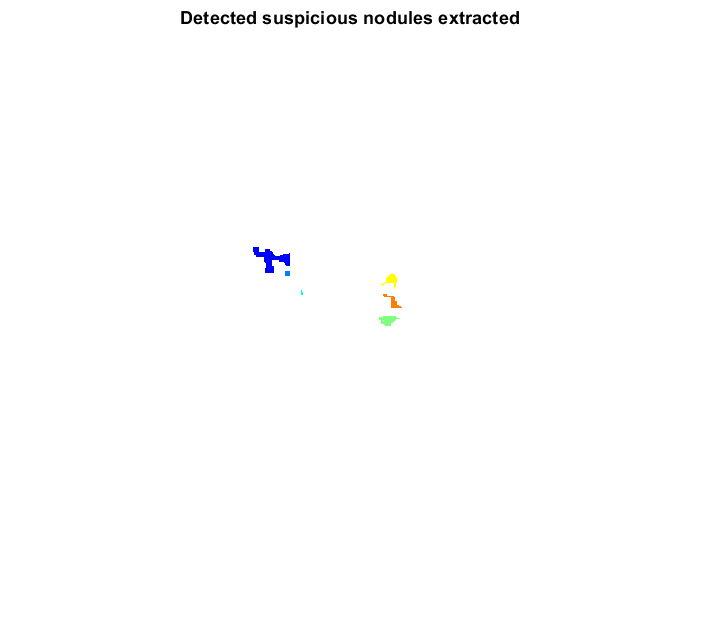

RGB = label2rgb(L);
figure, imshow(RGB),title('Detected suspicious nodules extracted');

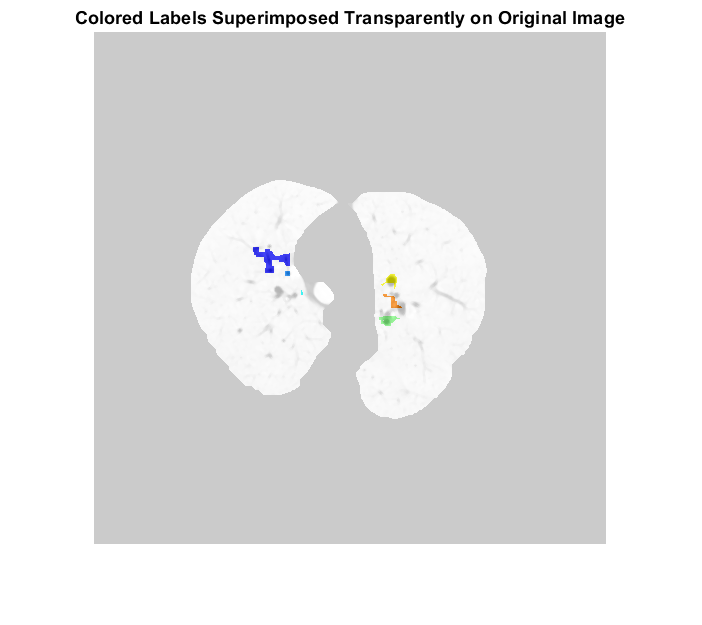


figure,
imshow(I_pre,[])
hold on
himage = imshow(RGB);
himage.AlphaData = 0.7;
title('Colored Labels Superimposed Transparently on Original Image')

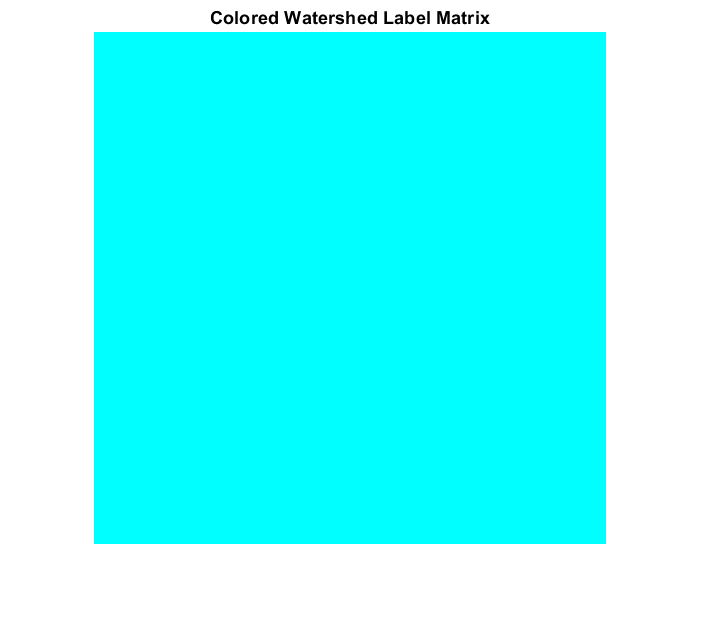

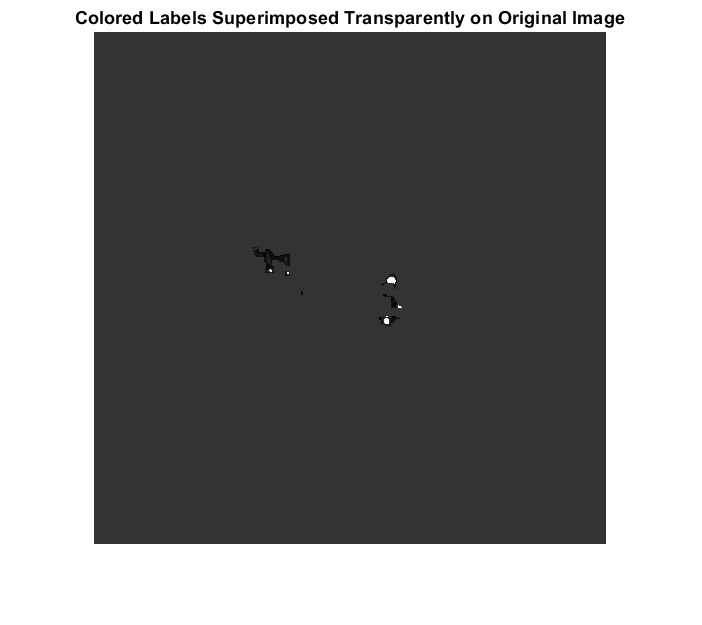


%Watershed on suspicious cells.
markcontrwatershed(nodules,strel('disk',3),strel(ones(1,1)));

%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

[truePos,falsePos] = falseTruePositives(nodules,dicomread('p1_seg7.dcm'));
truePos

truePos = 0.2850

falsePos

falsePos = 2.3025

## 5) Gaussian filter 

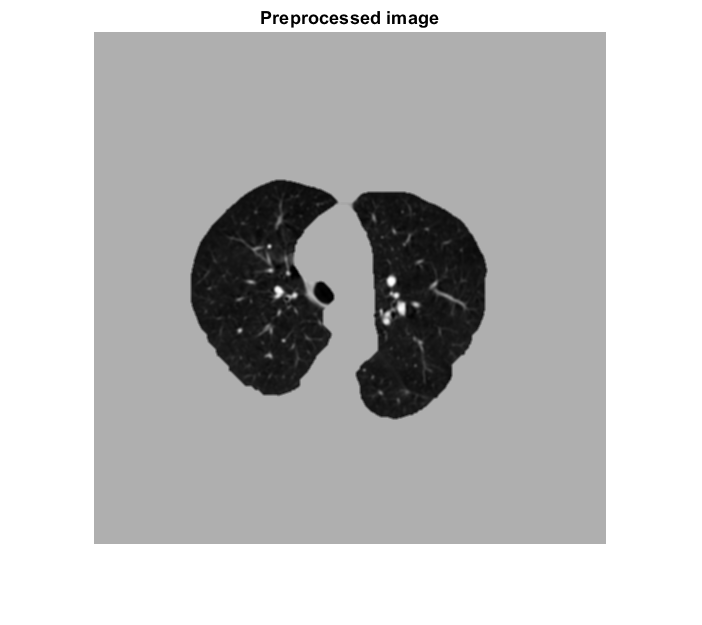

%Read in image and extract lungs 
I = dicomread('p1_img7.dcm');
preprocessedI = lungExtraction(I,strel('disk',15),1);

%Adaptive histogram doesnt seem to work. Removed it from the process.
I_pre = pre5(preprocessedI); 
figure,imshow(I_pre,[]);title('Preprocessed image');

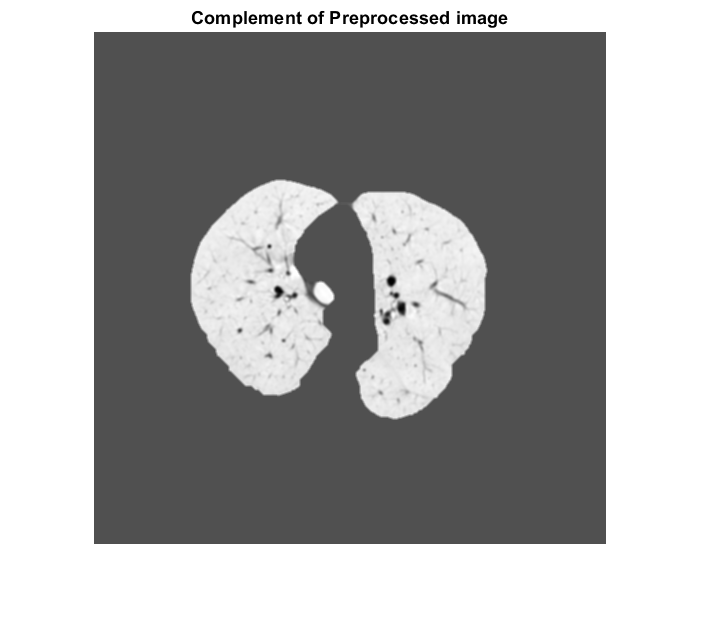


%Complement the gabor image to change background to white from black
I_pre = imcomplement(I_pre);
figure,imshow(I_pre,[]);title('Complement of Preprocessed image');

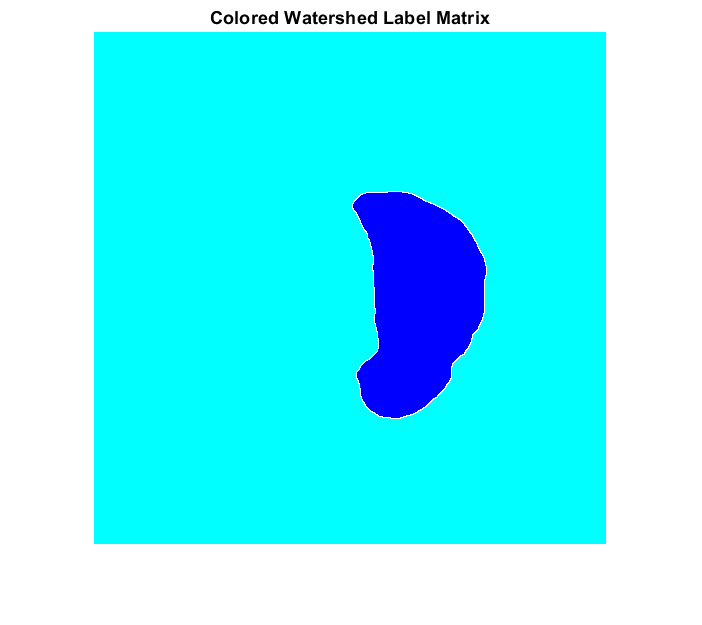

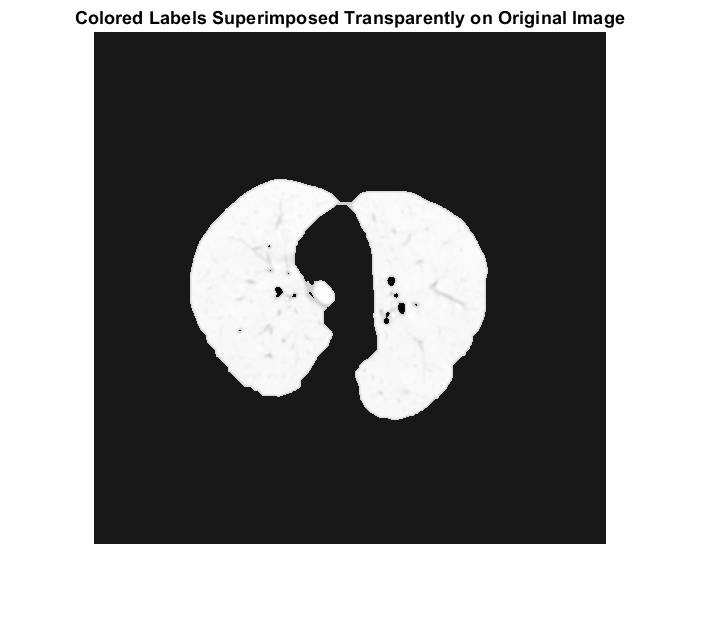


%Apply watershed on preprocessed image
label = markcontrwatershed(I_pre,strel('disk',13),strel(ones(5,5))); 


%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

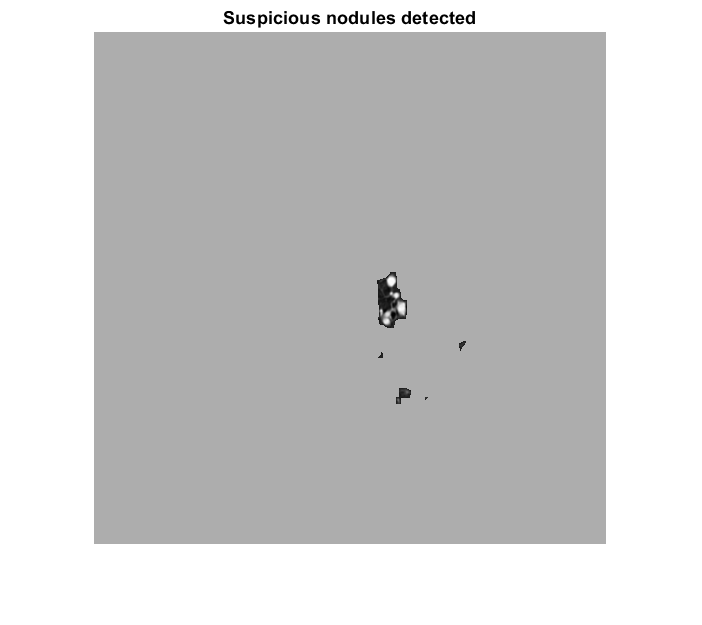


%Get suspicious nodules
nodules = noduleExtraction(label,preprocessedI);


%Label suspicious nodules
[L, num] = bwlabel(nodules);
disp (num);

     5



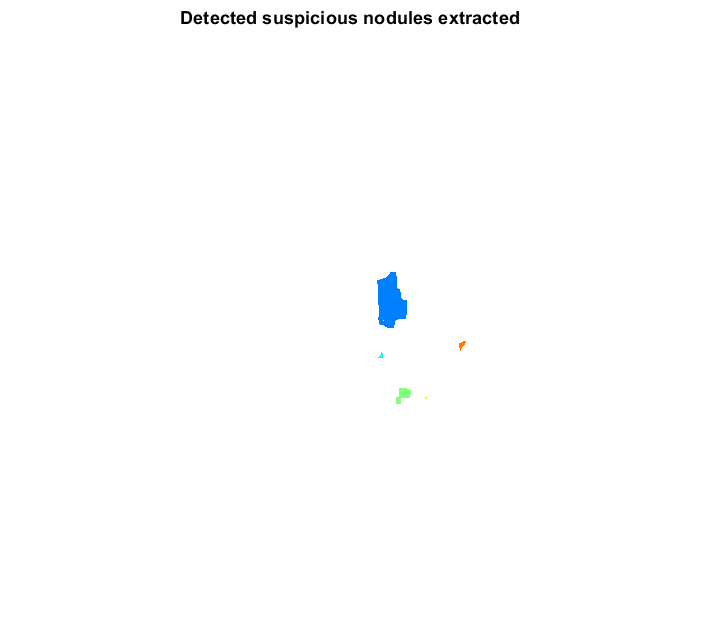

RGB = label2rgb(L);
figure, imshow(RGB),title('Detected suspicious nodules extracted');

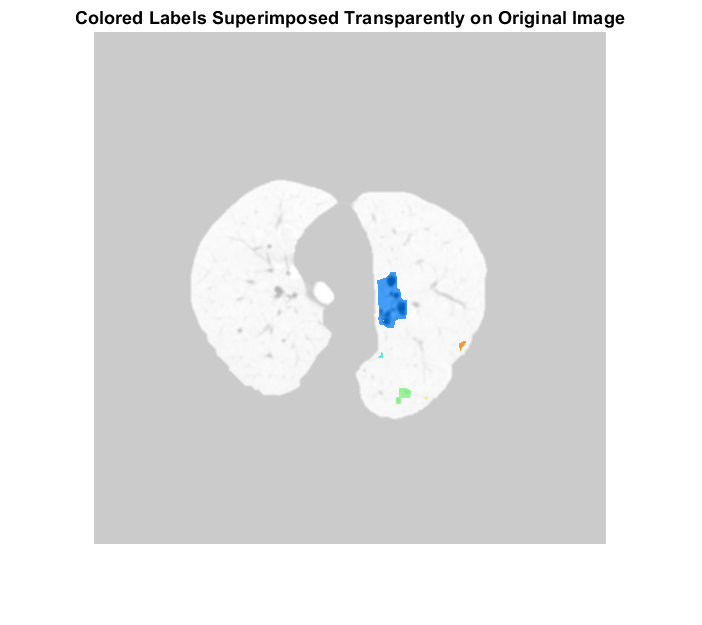


figure,
imshow(I_pre,[])
hold on
himage = imshow(RGB);
himage.AlphaData = 0.7;
title('Colored Labels Superimposed Transparently on Original Image')

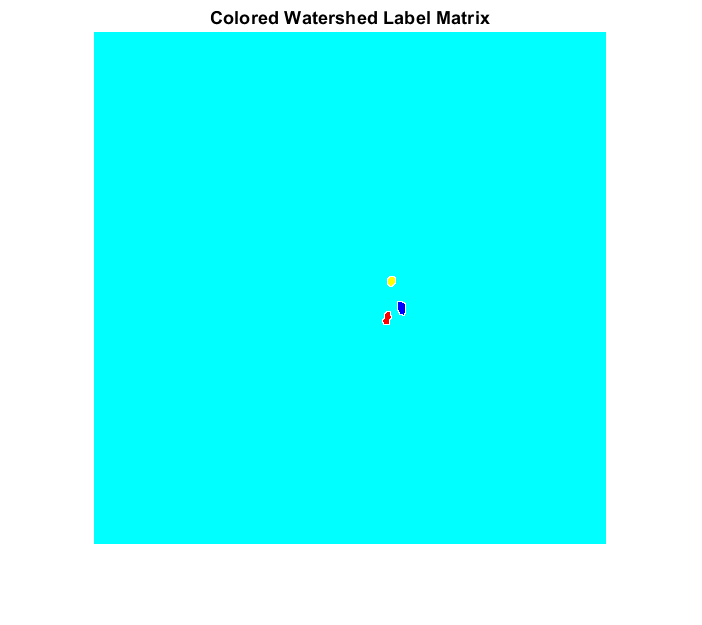

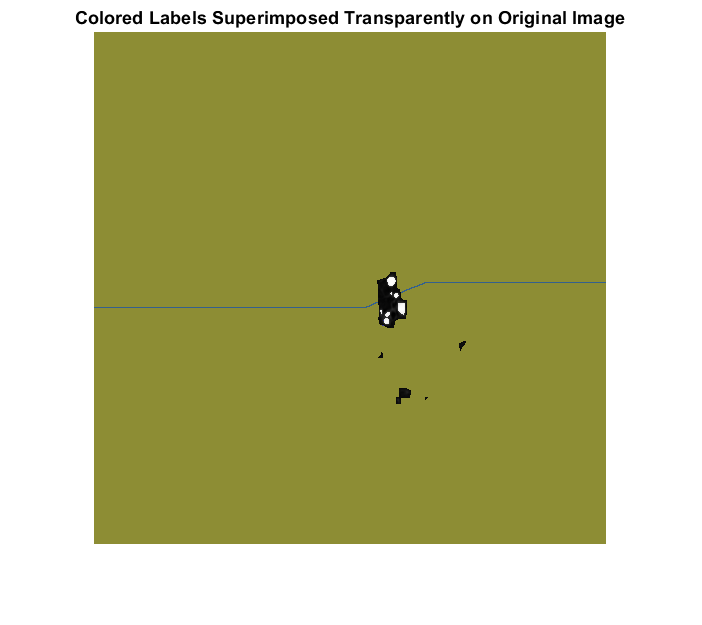


%Watershed on suspicious cells.
markcontrwatershed(nodules,strel('disk',3),strel(ones(1,1)));

%Ground truth
I = dicomread('p1_seg7.dcm');
figure,imshow(I,[]),title('Cancer location');

[truePos,falsePos] = falseTruePositives(nodules,dicomread('p1_seg7.dcm'));
truePos

truePos = 0.6900

falsePos

falsePos = 3.0475

## 6) Adaptive histogram equalization (Not used)

### Functions

Reference for gabor filter code: [https://www.mathworks.com/matlabcentral/fileexchange/23253-gabor-filter](https://www.mathworks.com/matlabcentral/fileexchange/23253-gabor-filter)

Parameters used in the gabor filter: [http://matlabserver.cs.rug.nl/edgedetectionweb/web/edgedetection_params.html](http://matlabserver.cs.rug.nl/edgedetectionweb/web/edgedetection_params.html)

Further (general) explanation for gabor filter: [https://medium.com/@anuj_shah/through-the-eyes-of-gabor-filter-17d1fdb3ac97](https://medium.com/@anuj_shah/through-the-eyes-of-gabor-filter-17d1fdb3ac97)

function [result]    = gabor(image)
% an example to demonstrate the use of gabor filter.
% requires lena.jpg in the same path.
% the results mimic:
% http://matlabserver.cs.rug.nl/edgedetectionweb/web/edgedetection_examples
% .html
% using default settings (except for in radians instead of degrees)
%
% note that gabor_fn only take scalar inputs, and multiple filters need to
% be generated using (nested) loops
%
% also, apparently the scaling of the numbers is different from the example
% software at
% http://matlabserver.cs.rug.nl
% but are consistent with the formulae shown there
    lambda  = 3;
    theta   = 0;
    psi     = [0 pi/2];
    gamma   = 0.5;
    bw      = 1.5;
    N       = 16;
    img_in = im2double(image);
    %img_in(:,:,2:3) = [];   % discard redundant channels, it's gray anyway
    img_out = zeros(size(img_in,1), size(img_in,2), N);
    for n=1:N
        gb = gabor_fn(bw,gamma,psi(1),lambda,theta)...
            + 1i * gabor_fn(bw,gamma,psi(2),lambda,theta);
        % gb is the n-th gabor filter
        img_out(:,:,n) = imfilter(img_in, gb, 'symmetric');
        % filter output to the n-th channel
        theta = theta + 2*pi/N;
        % next orientation
    end
    img_out_disp = sum(abs(img_out).^2, 3).^0.5;
    % default superposition method, L2-norm
    img_out_disp = img_out_disp./max(img_out_disp(:));
    % normalize
    result = img_out_disp;
end

function gb=gabor_fn(bw,gamma,psi,lambda,theta)
% bw    = bandwidth, (1)
% gamma = aspect ratio, (0.5)
% psi   = phase shift, (0)
% lambda= wave length, (>=2)
% theta = angle in rad, [0 pi) 
    sigma = lambda/pi*sqrt(log(2)/2)*(2^bw+1)/(2^bw-1);
    sigma_x = sigma;
    sigma_y = sigma/gamma;
    sz=fix(8*max(sigma_y,sigma_x));
    if mod(sz,2)==0, sz=sz+1;end
    % alternatively, use a fixed size
    % sz = 60;
     
    [x y]=meshgrid(-fix(sz/2):fix(sz/2),fix(sz/2):-1:fix(-sz/2));
    % x (right +)
    % y (up +)
    % Rotation 
    x_theta=x*cos(theta)+y*sin(theta);
    y_theta=-x*sin(theta)+y*cos(theta);
     
    gb=exp(-0.5*(x_theta.^2/sigma_x^2+y_theta.^2/sigma_y^2)).*cos(2*pi/lambda*x_theta+psi);
    %imshow(gb/2+0.5);
end

% Method 1: Median filter -> Gaussian filter -> Adaptive histogram equalization -> Gabor filter
function [I_m_g_h_gab] = pre1(I)
    % Median filtering
    I_m = medfilt2(I,[3 3]); 
    % Gaussian filtering
    k = fspecial('gaussian',[5 5],2);
    I_m_g = imfilter(I_m,k);
    % Adaptive histogram equalization
    %I_m_g_h = adapthisteq(I_m_g);
    % Gabor filter
    I_m_g_h_gab = gabor(I_m_g);
end

% Method 2: Gabor filter
function [I_gab] = pre2(I)
    I_gab = gabor(I);
end

% Method 3: Median filter -> Gaussian filter
function [I_m_g] = pre3(I)
    % Median filtering
    I_m = medfilt2(I,[3 3]); 
    % Gaussian filtering
    k = fspecial('gaussian',[5 5],2);
    I_m_g = imfilter(I_m,k);
end

% Method 4: Median filter
function [I_m] = pre4(I)
    I_m = medfilt2(I,[3 3]); 
end

% Method 5: Gaussian filter
function [I_g] = pre5(I)
    k = fspecial('gaussian',[3 3],2);
    I_g = imfilter(I,k);
end

% Method 6: Adaptive histogram equalization
function [I_h] = pre6(I)
    I_h = adapthisteq(I);
end